# LAB 1 - Bo-Chang, Lin - MAT 275

# Exercise 1

Define input variable theta as discretized row vector (i.e. array)

theta = [0 pi/5 pi/3 pi/2 3*pi/2 4*pi/3 5*pi/4];

Define radius

r = 5;

Define x and y in terms of theta and r

format short
x= r*cos(theta)

x =     5.0000    4.0451    2.5000    0.0000   -0.0000   -2.5000   -3.5355


y= r*sin(theta)

y =          0    2.9389    4.3301    5.0000   -5.0000   -4.3301   -3.5355


% Check that x and y satisfy the equation of a circle
sqrt(x.^2 + y.^2) % r = sqrt(x^2 + y^2) 

ans =     5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000


**Explain results here.** Do x and y satisfy the equation of a circle? Why or why not?

How does the vector output at the end confirm your answer?

Yes, x and y satisfy the equation of a circle. All the 7 entries in the last vector output are equal to 5 and it mach the given radius.

# Exercise 2

Define t-vector

t = linspace(6,30,((30-6)/0.3)+1); % better way t=6:0.3:30

Define y-vector

y = exp(t/15).*cos(2*t)./(0.6*(t.^3) + 9);

### Part (a)

Plot results (should have 3 plots total)

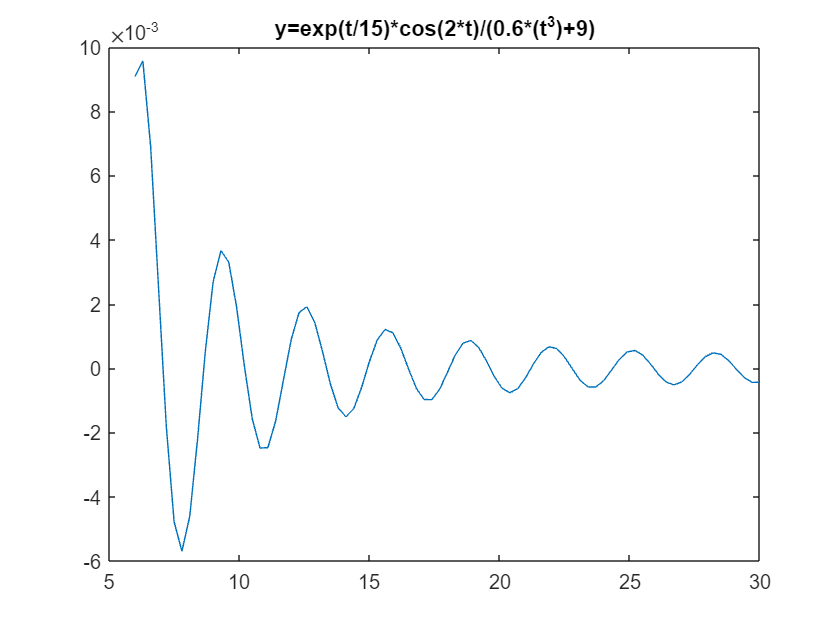

figure;
plot(t,y);
title("y=exp(t/15)*cos(2*t)/(0.6*(t^3)+9)")

### Part (b)

Plot results as data points only and as data points with line.

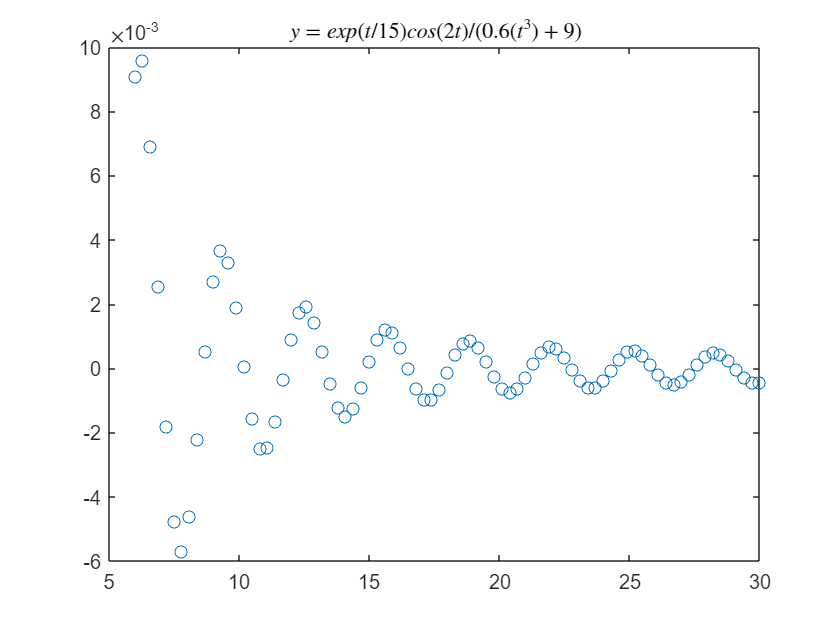

% For data points only
figure %creates another figure window
plot(t,y,'o');
title("$y=exp(t/15)cos(2t)/(0.6(t^3)+9)$",'interpreter','latex')

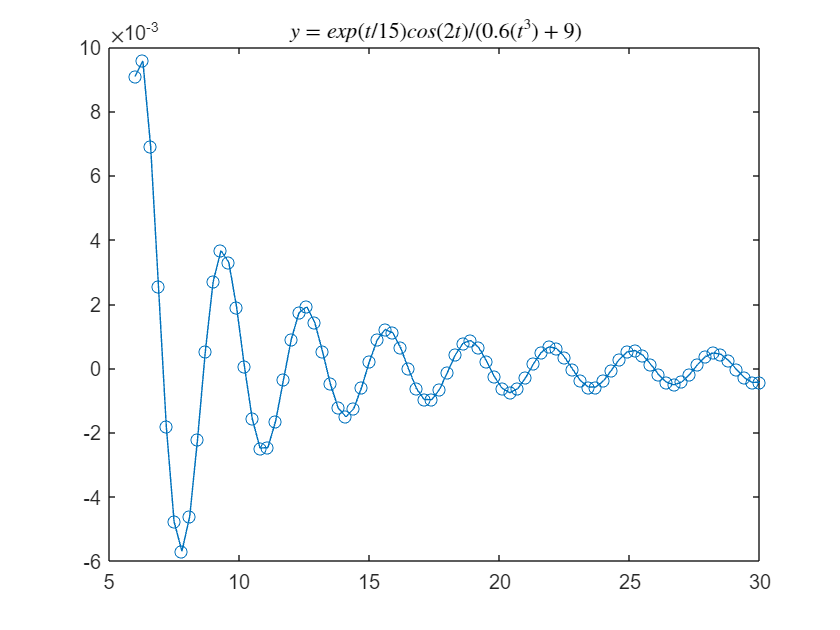

% For data points with line
figure %creates another figure window
plot(t,y,'o-');
title("$y=exp(t/15)cos(2t)/(0.6(t^3)+9)$",'interpreter','latex')

# Exercise 3

Create t-vector (choose enough elements so that plot is smooth!)

t = 0:0.001:10;

Define x, y, x components in terms of t

x = 9*cos(5*t); y = 9*sin(5*t); z = 6*t;

Plot results

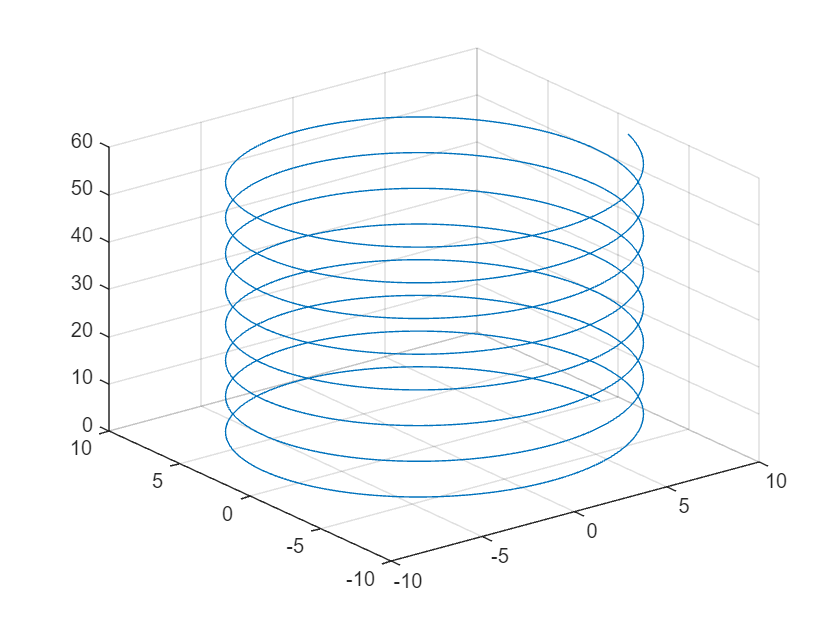

figure;
plot3(x,y,z)
grid on

# Exercise 4

Define input variable as vector

x= -pi/4:0.0001:pi/4;

Define y and z

y = sin(4*x);
z = 4*x - 32/3*x.^3;

Plot results

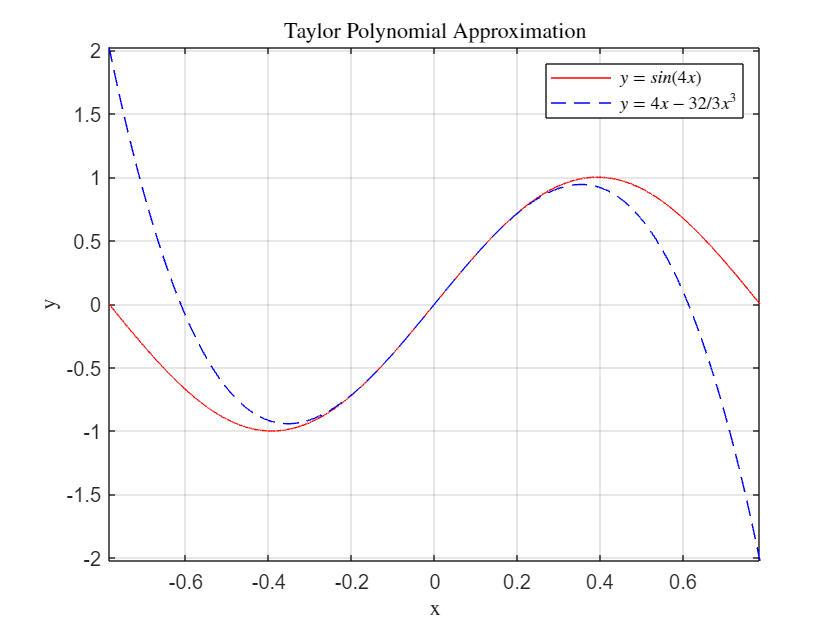

figure;
plot(x,y,'r-',x,z,'b--')
axis tight;
grid on
title("Taylor Polynomial Approximation","Interpreter","latex")
xlabel("x","Interpreter","latex")
ylabel("y","Interpreter","latex")
legend("$y=sin(4x)$","$y=4x-32/3x^3$","Interpreter","latex")

# Exercise 5

type Lab1_Ex5.m % here I renamed it for file sorting purpuse

x = 0:0.001:8 ; % define the vector x in the interval [0 ,8]
y1 = f (x,640) ; % compute the solution with C = 640
y2 = f (x,1070) ; % compute the solution with C = 1070
y3 = f (x,1600) ; % compute the solution with C = 1600
plot (x,y1,'b-',x,y2,'r--',x,y3,'k-.') 
title ("Solutions to $dy/dx = -9x -17x^2 - 14cos(x)$","Interpreter","latex") 
legend ("C = 640","C = 1070","C = 1600","Interpreter","latex") 
xlabel("x","Interpreter","latex")
ylabel("y","Interpreter","latex")

function y = f(x,C)
% fill -in with the expression for the general solution
y = -9/2*x -17/3*x.^3 - 14*sin(x) + C;
end


Run your M-file--i.e. execute the M-file

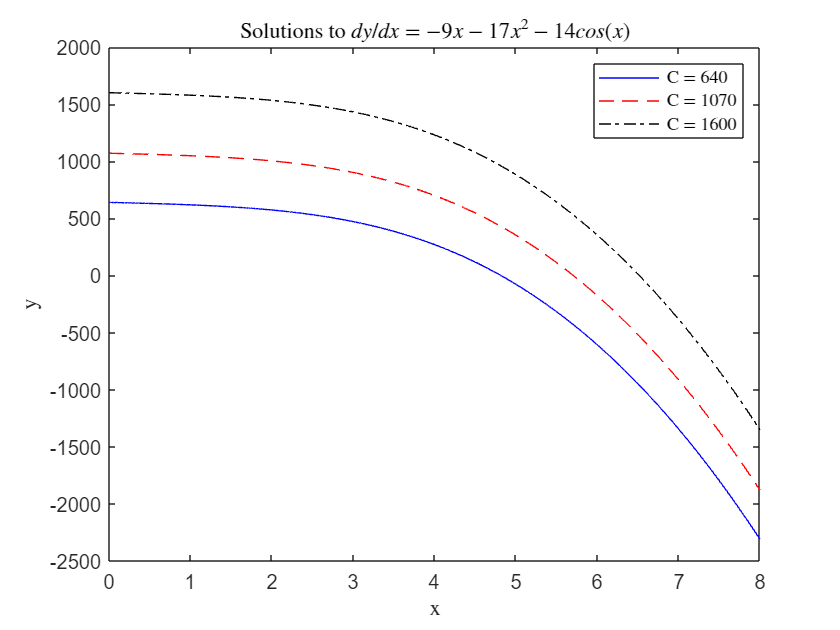

run 'Lab1_Ex5.m'

# Exercise 6

### Part (a)

Define g as anonymous function

g = @(x,y)(x.^3/y.^7 + cos(4*x.*exp(8*y))/(x.^2 + 2));

Evaluate g at the given values of x and y

g(5,-4)

ans = 0.0294

### Part (b)

Clear the function g out of the workspace

clear g

Print out g.m contents

type 'Lab1_Ex6_g.m' % here I renamed it for file sorting purpuse

function Lab1_Ex6_g(x,y)
% Omit the equal sign here since it's an easy single output function
x.^3/y.^7 + cos(4*x.*exp(8*y))/(x.^2 + 2)
end


Evaluate g at the given values of x and y

Lab1_Ex6_g(5,-4)

ans = 0.0294

The End!!!